# MATLAB 101

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr/)

We explain the basics of MATLAB. The strengths of the MATLAB are

- Intuitive and efficient linear algebra operations.

- Supports tons of mathematical functions.

- Platform independent.

- Many toolboxes (e.g., parallel computing, signal processing, big data, ...)

- Graphic user interface.

- Powerful editor, debugger, and profiler.

- Supports compiler.

- Last but not least: QSpace, one of the most powerful tensor network libraries and used by my group, runs on MATLAB.

You can try out the following commands in three different ways:

(1) First click a section. The selected section will be highlighted with light blue borders. Then click "Live Editor" (top left), then "Run Section" (top right) (see a screenshot below). It can be done by shortcut command Ctrl+Enter for Windows or Command+Enter for MacOS.

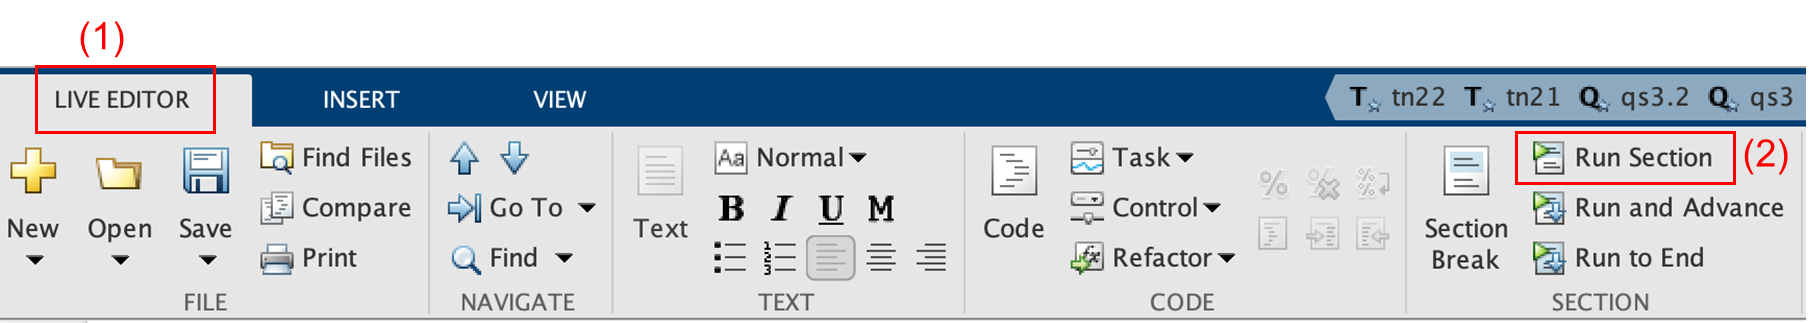

(2) Type the commands into the "Command Window".

(3) Write a MATLAB script or function (.m file) under the `MyWork` directory. You can run it (i) by typing the name of the script or function (only the file name, without the `.m` extension) in the "Command Window", or (ii) by clicking "Editor" then "Run" (shortcuts: F5 in Windows or Option+Command+R in MacOS) (see a screenshot below).

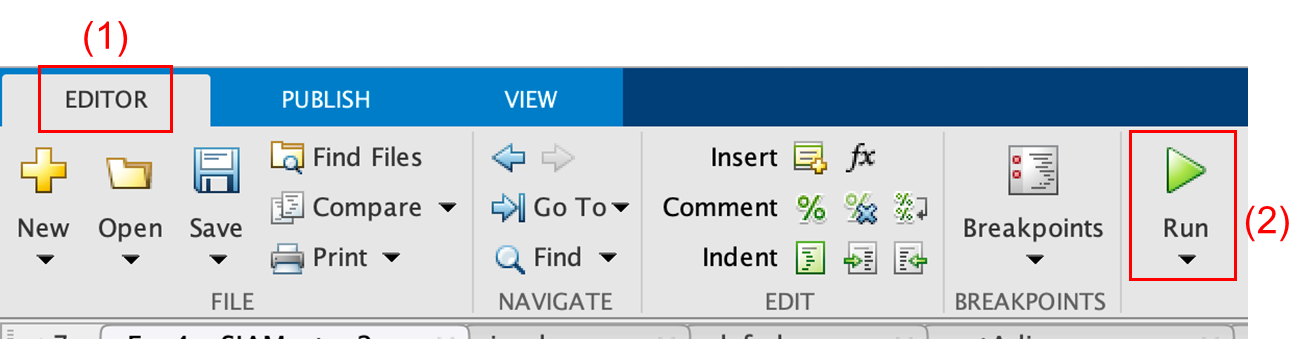

**For this tutorial, there is no exercise problem. Experienced users of MATLAB may skip this tutorial, and move on to the next tutorials.**

## Initialization

First, clear memory to avoid any possible collision.

clear % clear memory

## Basic algebra

Algebra for numbers. MATLAB basically uses double type variables. In practice, this policy helps us to avoid data conversion mistakes (which frequently happen in, e.g., C programming).

A = 1; % assign A = 1
B = 2; % assign B = 2
A+B

ans = 3

A-B

ans = -1

A*B

ans = 2

A/B

ans = 0.5000

Also there are some predefined constants.

i % imaginary number \sqrt{-1}

ans = 0.0000 + 1.0000i

1i % the same

ans = 0.0000 + 1.0000i

pi % pi

ans = 3.1416

e is not a predefined constant.

e % doesn't work

ans = 2.7183

When a live in a section contains an error, as here, subsequent lives are not executed. Therefore, fix the error (here: comment it out) to be able to proceed.

exp(1) % Euler constant

ans = Inf

For unusual calculations, MATLAB also supports `Inf` (infinity) and `NaN` (not-a-number).

1/0 % + infinity

ans = -Inf

-1/0 % - infinity

ans = NaN

0/0 % not-a-number

To suppress displaying result, put `;` at the end of command.

A = 1; B = 2;
C = A+B  % substitute to C

C = 3

C = A+B; % suppress displaying result by putting ';' to the end

## Numerical precision

Most of numeric variables in MATLAB have so-called double precision, unless specified. It means that the numbers beyond 16 digits to the right of the leading significant number are rounded. A simple example to see this is:

clear
sqrt(2)^2 - 2

ans = 4.4409e-16

Analytically, $(\sqrt{2})^2 - 2$ should be strictly zero, but in numerics, the digits below $\sim 10^{-16}$ were rounded at each of `sqrt` and `^2`, hence finite value $\sim 10^{-16}$. Thus in most of numerical methods, such small numbers are *de facto* zeros. Of course, the precision is relative to the magnitude of numbers. To see the precision for a numeric variable, you can use the `eps` command.

eps(2)

ans = 4.4409e-16

eps(1e10)

ans = 1.9073e-06

eps([1 1e3 1e5])

ans = 1.0e-10 *

    0.0000    0.0011    0.1455


## Vectors and matrices

We can create vectors and matrices.

clear
A = [1 2 3] % row vector

A =      1     2     3


A = [1,2,3] % row vector (space and , work in the same way)

A =      1     2     3


A = [1;2;3] % column vector

A =      1
     2
     3


A = [1 2; 3 4] % matrix

A =      1     2
     3     4


The vector whose elements constitute the arithmetic series can be generated easily.

A = (1:3) % row vector, arithmetic series

A =      1     2     3


A = (1:3:10) % start from 1, step size = 3, up to <= 10

A =      1     4     7    10


A = (10:12:100) % starting term can be different

A =     10    22    34    46    58    70    82    94


A = (1:3:2) % 1

A = 1

A = (1:3:0) % empty


A =

  1×0 empty double row vector



A = (1:-3:-10) % also negative step size possible

A =      1    -2    -5    -8


Functions are available for generating commom types of vectors, matices, and multi-dimensional arrays with specified sizes.

A = rand(3,2) % 3*2 matrix with random elements in interval (0,1)

A =     0.5278    0.7505
    0.4116    0.5835
    0.6026    0.5518


A = ones(3,2) % 3*2 matrix with all ones

A =      1     1
     1     1
     1     1


A = zeros(3,2) % 3*2 matrix with all zeros

A =      0     0
     0     0
     0     0


A = rand(3) % 3*3 matrix with random elements

A =     0.5836    0.7196    0.9713
    0.5118    0.9962    0.3464
    0.0826    0.3545    0.8865


A = ones(3) % 3*3 matrix with all ones

A =      1     1     1
     1     1     1
     1     1     1


A = zeros(3) % 3*3 matrix with all zeros

A =      0     0     0
     0     0     0
     0     0     0


A = rand(3,2,3) % multi-dimensional array

A = A(:,:,1) =

    0.4547    0.1257
    0.4134    0.3089
    0.2177    0.7261


A(:,:,2) =

    0.7829    0.8432
    0.6938    0.9223
    0.0098    0.7710


A(:,:,3) =

    0.0427    0.7295
    0.3782    0.2243
    0.7043    0.2691


A = eye(3) % 3*3 identity matrix

A =      1     0     0
     0     1     0
     0     0     1


A = eye(3,4) % 3*4 matrix whose diagonal elements are 1 and others are 0

A =      1     0     0     0
     0     1     0     0
     0     0     1     0


A = eye(4,2) % 4*2 matrix whose diagonal elements are 1 and others are 0

A =      1     0
     0     1
     0     0
     0     0


A = eye(3,3,3) % doesn't work

You can also define the matrix of `NaN`'s and `Inf`'s.

A = nan(2,3)

A =    NaN   NaN   NaN
   NaN   NaN   NaN


A = inf(2,3)

A =    Inf   Inf   Inf
   Inf   Inf   Inf


## Matrix operations, element-wise operations

In MATLAB, matrix operations are intuitive (and efficient).

clear
A = rand(3,2)

A =     0.6730    0.2364
    0.4775    0.1771
    0.6237    0.8296


B = rand(2,4)

B =     0.7669    0.1079    0.0991    0.1932
    0.9345    0.1822    0.4898    0.8959


A*B % matrix multiplication

ans =     0.7371    0.1157    0.1825    0.3419
    0.5317    0.0838    0.1341    0.2510
    1.2536    0.2185    0.4681    0.8638


B*A % doesn't work
A+B % doesn't work
A-B % doesn't work

The reason why the last three commands fail is that `A` and `B` have different sizes. But they do work if `B` and `A` have the same dimensions.

B = rand(3,2)

B =     0.0991    0.7725
    0.0442    0.3119
    0.5573    0.1790


A+B

ans =     0.7721    1.0089
    0.5217    0.4891
    1.1810    1.0086


A-B

ans =     0.5739   -0.5361
    0.4333   -0.1348
    0.0664    0.6507


A*B % doesn't work
A.*B % element-wise multiplication

ans =     0.0667    0.1827
    0.0211    0.0553
    0.3476    0.1485


A./B % element-wise division

ans =     6.7921    0.3061
   10.8114    0.5678
    1.1192    4.6353


A/B % equivalent to mrdivide function, giving a solution C such that C*B = A

ans =     0.0274         0    1.2028
    0.0321         0    0.8511
    0.8497         0    0.9681


C = A/B;
C*B-A % output will be 0, up to double precision

ans = 1.0e-15 *

    0.2220   -0.0555
    0.0555         0
    0.4441    0.2220


## Size commands

The size of vectors, matrices, and multi-dimensional arrays can be retrieved by the following functions.

clear
A = rand(3,2)

A =     0.3390    0.9064
    0.2101    0.6289
    0.5102    0.1015


size(A) % dimensions of A

ans =      3     2


size(A,1) % 1st dimension of A

ans = 3

size(A,2) % 2nd dimension of A

ans = 2

numel(A) % total number of elements

ans = 6

A = rand(3,1) % vector

A =     0.3909
    0.0546
    0.5013


size(A)

ans =      3     1


A = rand(3,2,3)

A = A(:,:,1) =

    0.4317    0.4857
    0.9976    0.8944
    0.8116    0.1375


A(:,:,2) =

    0.3900    0.7136
    0.9274    0.6183
    0.9175    0.3433


A(:,:,3) =

    0.9360    0.6465
    0.1248    0.8332
    0.7306    0.3983


size(A)

ans =      3     2     3


numel(A)

ans = 18

## Transpose and Hermitian conjugation

clear
A = rand(3,2)+1i*rand(3,2) 

A =    0.7498 + 0.3304i   0.5523 + 0.7565i
   0.8352 + 0.6195i   0.9791 + 0.4139i
   0.3225 + 0.3606i   0.5493 + 0.4923i


A' % Hermitian conjugate

ans =    0.7498 - 0.3304i   0.8352 - 0.6195i   0.3225 - 0.3606i
   0.5523 - 0.7565i   0.9791 - 0.4139i   0.5493 - 0.4923i


A.' % transpose

ans =    0.7498 + 0.3304i   0.8352 + 0.6195i   0.3225 + 0.3606i
   0.5523 + 0.7565i   0.9791 + 0.4139i   0.5493 + 0.4923i


(1i)' % complex conjugate for a number

ans = 0.0000 - 1.0000i

## Logical variables and operations

In addition to double type and character type (shortly mentioned in the cell array section), there is also logical data type.

clear
true % logical variable

ans = logical
   1


false

ans = logical
   0


double(true) % 1

ans = 1

double(false) % 0

ans = 0

A = true(3,2) % logical array is possbile

A = 3×2 logical array
   1   1
   1   1
   1   1


A'

ans = 2×3 logical array
   1   1   1
   1   1   1


2 > 1 % true

ans = logical
   1


2 == 2 % true (== : the same)

ans = logical
   1


2 ~= 2 % false (~= : not the same)

ans = logical
   0


2 >= 1 % true (>= : left is larger than or the same as right)

ans = logical
   1


2 <= 1 % false (<= : left is smaller than or the same as right)

ans = logical
   0


0 > 1 % false

ans = logical
   0


~(2 > 1) % logical NOT operation

ans = logical
   0


(2 > 1) && (3 > 1) % logical AND operation

ans = logical
   1


(2 > 1) && (0 > 1)

ans = logical
   0


(2 > 1) || (3 > 1) % logical OR operation

ans = logical
   1


(2 > 1) || (0 > 1)

ans = logical
   1


Logical variables also can consitute an array.

true(3,3)

ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


The array of logical variables is useful in various operations. For example, we can extract the subvector or submatrix whose elements satisfy certain condition, e.g., being larger than 0.5.

A = rand(1,6)

A =     0.6947    0.9727    0.3278    0.8378    0.7391    0.9542


B = (A > 0.5) % logical vector

B = 1×6 logical array
   1   1   0   1   1   1


A(B) % only the elements of A larger than 0.5

ans =     0.6947    0.9727    0.8378    0.7391    0.9542


C = find(B) % indices of B which is true

C =      1     2     4     5     6


A(C) % the same as A(B), but A(B) is faster

ans =     0.6947    0.9727    0.8378    0.7391    0.9542


A = rand(4,3)

A =     0.0319    0.2304    0.6604
    0.3569    0.7111    0.0476
    0.6627    0.6246    0.3488
    0.2815    0.5906    0.4513


B = (A > 0.5) % logical 4*3 matrix

B = 4×3 logical array
   0   0   1
   0   1   0
   1   1   0
   0   1   0


A(B) % the vector of the elements of A larger than 0.5

ans =     0.6627
    0.7111
    0.6246
    0.5906
    0.6604


C = find(B) % indices of B which is true (linear indexing)

C =      3
     6
     7
     8
     9


A(C) % the same as A(B), but A(B) is faster

ans = 5×1
    0.6627
    0.7111
    0.6246
    0.5906
    0.6604


## Accessing the elements and submatrices of matrices

We can access the elements and submatrices as follows. Note that the indexing in MATLAB starts from 1, not 0.

clear
A = rand(5,5)

A = 5×5
    0.2409    0.1378    0.8068    0.4494    0.6671
    0.7150    0.8367    0.5038    0.9635    0.5864
    0.8562    0.1386    0.4896    0.0423    0.6751
    0.2815    0.5882    0.8770    0.9730    0.3610
    0.7311    0.3662    0.3531    0.1892    0.6203


A(1,3) % Element at row 1, column 3

ans = 0.8068

A(1,:) % Row vector at row 1 (':' means all possible indices)

ans = 1×5
    0.2409    0.1378    0.8068    0.4494    0.6671


A(:,3)

ans = 5×1
    0.8068
    0.5038
    0.4896
    0.8770
    0.3531


A(:,:)

ans = 5×5
    0.2409    0.1378    0.8068    0.4494    0.6671
    0.7150    0.8367    0.5038    0.9635    0.5864
    0.8562    0.1386    0.4896    0.0423    0.6751
    0.2815    0.5882    0.8770    0.9730    0.3610
    0.7311    0.3662    0.3531    0.1892    0.6203


A(:) % column vector with all the elements of A

ans = 25×1
    0.2409
    0.7150
    0.8562
    0.2815
    0.7311
    0.1378
    0.8367
    0.1386
    0.5882
    0.3662


A(0,1) % doesn't work (indexing starts from 1 in MATLAB)
A(2:3,3:5) % submatrix at the intersection of row 2-3 and column 3-5

ans = 2×3
    0.5038    0.9635    0.5864
    0.4896    0.0423    0.6751


A(2:3,3:end) % 'end' means the last index

ans = 2×3
    0.5038    0.9635    0.5864
    0.4896    0.0423    0.6751


A(1:2:5,2:4) % intersections of rows 1, 3, 5 with columns 2 to 4

ans = 3×3
    0.1378    0.8068    0.4494
    0.1386    0.4896    0.0423
    0.3662    0.3531    0.1892


A(1:2:end,2:end) % intersections of rows 1,3,5 with columns 2 to 5

ans = 3×4
    0.1378    0.8068    0.4494    0.6671
    0.1386    0.4896    0.0423    0.6751
    0.3662    0.3531    0.1892    0.6203


A(10,7) % doesn't work since the index is out of range

We can also access the elements and submatrices by using logical indexing.

ok = [true false true true false];
A(:,ok) % columns 1, 3, 4

ans = 5×3
    0.2409    0.8068    0.4494
    0.7150    0.5038    0.9635
    0.8562    0.4896    0.0423
    0.2815    0.8770    0.9730
    0.7311    0.3531    0.1892


If a logical indexing vector is shorter than the corresponding size, the parts (e.g. rows, columns) from the first are considered.

A(:,[true true]) % columns 1, 2

ans = 5×2
    0.2409    0.1378
    0.7150    0.8367
    0.8562    0.1386
    0.2815    0.5882
    0.7311    0.3662


The position indexing (using integer indices) and the logical indexing can be combined.

A(1:2,ok) % combine position and logical indexing

ans = 2×3
    0.2409    0.8068    0.4494
    0.7150    0.5038    0.9635


In the same way, we can substitute the values.

A = rand(5,5)

A = 5×5
    0.8112    0.2312    0.3317    0.0943    0.7360
    0.0193    0.4035    0.1522    0.9300    0.7947
    0.0839    0.1220    0.3480    0.3990    0.5449
    0.9748    0.2684    0.1217    0.0474    0.6862
    0.6513    0.2578    0.8842    0.3424    0.8936


A(2,3) = 100 % substitute to a single element

A = 5×5
    0.8112    0.2312    0.3317    0.0943    0.7360
    0.0193    0.4035  100.0000    0.9300    0.7947
    0.0839    0.1220    0.3480    0.3990    0.5449
    0.9748    0.2684    0.1217    0.0474    0.6862
    0.6513    0.2578    0.8842    0.3424    0.8936


A(3:4,:) = 200 % substitute to two columns by the uniform value 200

A = 5×5
    0.8112    0.2312    0.3317    0.0943    0.7360
    0.0193    0.4035  100.0000    0.9300    0.7947
  200.0000  200.0000  200.0000  200.0000  200.0000
  200.0000  200.0000  200.0000  200.0000  200.0000
    0.6513    0.2578    0.8842    0.3424    0.8936


A(2:4,4:end) = 2 % substitute to a submatrix by the uniform value 2

A = 5×5
    0.8112    0.2312    0.3317    0.0943    0.7360
    0.0193    0.4035  100.0000    2.0000    2.0000
  200.0000  200.0000  200.0000    2.0000    2.0000
  200.0000  200.0000  200.0000    2.0000    2.0000
    0.6513    0.2578    0.8842    0.3424    0.8936


A(:) = 0 % substitute all the elements by 0

A = 5×5
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


In addition to indexing as (row index, column index), linear indexing is also available. The linear index is 1 for the upper left corner elements. Then the index increases from top to bottom, then from left to right.

A = rand(3,3)

A = 3×3
    0.0548    0.1955    0.8778
    0.3037    0.7202    0.5824
    0.0462    0.7218    0.0707


A(1) % = A(1,1)

ans = 0.0548

A(3) % = A(3,1)

ans = 0.0462

A(4) % = A(4,1)

ans = 0.1955

B = A(:) % column vector with all the elements of A

B = 9×1
    0.0548
    0.3037
    0.0462
    0.1955
    0.7202
    0.7218
    0.8778
    0.5824
    0.0707


B(1)

ans = 0.0548

B(3)

ans = 0.0462

B(4)

ans = 0.1955

It is consistent also for multi-dimensional arrays.

A = rand(3,2,3)

A = A(:,:,1) =

    0.9227    0.5437
    0.8004    0.9848
    0.2859    0.7157


A(:,:,2) =

    0.8390    0.5607
    0.4333    0.2691
    0.4706    0.7490


A(:,:,3) =

    0.5039    0.1387
    0.6468    0.4756
    0.3077    0.3625


A(1)

ans = 0.9227

A(10)

ans = 0.5607

A(1,:,(1:2))

ans = ans(:,:,1) =

    0.9227    0.5437


ans(:,:,2) =

    0.8390    0.5607


A(1,:,[true true false]) % same as A(1,:,(1:2))

ans = ans(:,:,1) =

    0.9227    0.5437


ans(:,:,2) =

    0.8390    0.5607


## Reshape and permute matrices

We can reshape matrices, which keeps the total number of elements while changing `size(A)`.

clear
A = (1:9) % row vector

A = 1×9
     1     2     3     4     5     6     7     8     9


B = reshape(A,[3 3])

B = 3×3
     1     4     7
     2     5     8
     3     6     9


B(:) % same as A, except that B is column vector

ans = 9×1
     1
     2
     3
     4
     5
     6
     7
     8
     9


C = permute(B,[2 1]) % permute dimensions

C = 3×3
     1     2     3
     4     5     6
     7     8     9


B.' % for matrices, the permutation is the same as transpose

ans = 3×3
     1     2     3
     4     5     6
     7     8     9


## Sum and product

The sum and the product of vectors, matrices, and multi-dimensional array can be obtained by the following.

clear
sum(1:9) % sum integers from 1 to 9

ans = 45

A = reshape((1:9),[3 3])

A = 3×3
     1     4     7
     2     5     8
     3     6     9


sum(A) % row vector whose elements are the sum of individual columns

ans = 1×3
     6    15    24


sum(A,2) % sum over the 2nd dimension (along rows) -> result: column vector

ans = 3×1
    12
    15
    18


sum(A,1) % the same as sum(A) for matrix A

ans = 1×3
     6    15    24


sum(sum(A)) % the sum of all the elements

ans = 45

sum(A(:)) % the same

ans = 45

prod(A) % row vector whose elements are the product of individual column

ans = 1×3
     6   120   504


prod(A,2)

ans = 3×1
    28
    80
   162


prod(A,1)

ans = 1×3
     6   120   504


prod(A(:))

ans = 362880

## Eigendecomposition

One of the most important functions for physics is the eigendecomposition (also called spectral decomposition).

clear
A = rand(3,3);
A = (A+A') % symmetrize to make a Hermitian matrix

A = 3×3
    1.5762    0.9138    0.9693
    0.9138    0.0431    1.4993
    0.9693    1.4993    1.9618


D = eig(A) % the vector of eigenvalues

D = 3×1
   -0.8354
    0.8066
    3.6099


[U,D] = eig(A) % spectral decomposition A = U*D*U'

U = 3×3
   -0.1694   -0.8246    0.5398
    0.8919    0.1048    0.4400
   -0.4193    0.5559    0.7177


D = 3×3
   -0.8354         0         0
         0    0.8066         0
         0         0    3.6099


`U` is the unitary matrix whose columns are eigenvectors, and `D` is the diagonal matrix whose diagonal elements are eigenvalues. Check the accuracy of the eigendecomposition.

U*D*U' - A % should be zero up to numerical double precision ~ 1e-16

ans = 3×3
1.0e-15 *

    0.8882    0.3331    0.3331
    0.3331    0.7772    0.2220
    0.3331    0.2220    0.4441


abs(U*D*U' - A) < 10*max(eps(A(:))) % error comparable with the precision of A

ans = 3×3 logical array
   1   1   1
   1   1   1
   1   1   1


U'*U % left-unitarity

ans = 3×3
    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


U*U' % right-unitarity

ans = 3×3
    1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


Often, the zeros above and below the diagonal of `D` can be redundant. Then one may use:

[U,D] = eig(A,'vector')

U = 3×3
   -0.1694   -0.8246    0.5398
    0.8919    0.1048    0.4400
   -0.4193    0.5559    0.7177


D = 3×1
   -0.8354
    0.8066
    3.6099


## Singular value decomposition (SVD)

SVD is a key concept in the MPS methods. If the SVD is applied to the matrix whose elements are coefficient of bipartite quantum state, it provides the Schmidt decomposition.

clear
A = rand(3,3)

A = 3×3
    0.2866    0.5975    0.5492
    0.8008    0.8840    0.7284
    0.8961    0.9437    0.5768


S = svd(A) % the vector of singular values in decreasing order

S = 3×1
    2.1536
    0.2780
    0.0721


[U,S,V] = svd(A) % Singular value decomposition A  = U*S*V'

U = 3×3
   -0.3844    0.8406    0.3815
   -0.6484    0.0483   -0.7597
   -0.6571   -0.5395    0.5265


S = 3×3
    2.1536         0         0
         0    0.2780         0
         0         0    0.0721


V = 3×3
   -0.5657   -0.7331   -0.3776
   -0.6608    0.1290    0.7394
   -0.4933    0.6678   -0.5574


`U` is the unitary matrix whose columns are left-singular vectors, `S` is the diagonal matrix whose diagonal elements are singular values, and `V` is the unitary matrix whose columns are right-singular vectors.

U*S*V' - A % should be zero up to numerical double precision ~ 1e-16

ans = 3×3
1.0e-15 *

   -0.5551   -0.1110   -0.2220
   -0.5551    0.2220   -0.2220
   -0.5551         0   -0.4441


U*S*V - A % non-zero

ans = 3×3
    0.0137    0.0579   -0.0790
    0.0073    0.1049   -0.1606
   -0.0152    0.0996   -0.1745


U*U' % identity; U is unitary

ans = 3×3
    1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


U'*U % identity; U is unitary

ans = 3×3
    1.0000    0.0000    0.0000
    0.0000    1.0000   -0.0000
    0.0000   -0.0000    1.0000


V*V' % identity; V is unitary

ans = 3×3
    1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


V'*V % identity; V is unitary

ans = 3×3
    1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


Note that, simiarly to `eig` function without `'vector'` option, the shape of `S` differs depending on how we request the output of `svd`. Contrary to the eigendecomposition, SVD is applicable to non-symmetric or non-Hermitian matrix, even to non-square matrix.

A = rand(4,3)

A = 4×3
    0.0259    0.3723    0.3725
    0.4465    0.9371    0.5932
    0.6463    0.8295    0.8726
    0.5212    0.8491    0.9335


S = svd(A) % three singular values

S = 3×1
    2.3090
    0.2501
    0.2113


[U,S,V] = svd(A)

U = 4×4
   -0.2135   -0.2922   -0.8151   -0.4524
   -0.5099   -0.7754    0.3612    0.0907
   -0.5890    0.4642    0.3117   -0.5835
   -0.5895    0.3128   -0.3286    0.6683


S = 4×3
    2.3090         0         0
         0    0.2501         0
         0         0    0.2113
         0         0         0


V = 3×3
   -0.3989    0.4367    0.8063
   -0.6697   -0.7394    0.0691
   -0.6263    0.5125   -0.5874


Note that the sizes of `U`, `S`, and `V` are different.

U*S*V' - A

ans = 4×3
1.0e-15 *

    0.0555   -0.7772   -0.6661
    0.2776         0         0
    0.2220   -0.2220   -0.2220
    0.2220   -0.1110   -0.2220


U*U' % identity; U is unitary

ans = 4×4
    1.0000   -0.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000   -0.0000
   -0.0000   -0.0000    1.0000         0
   -0.0000   -0.0000         0    1.0000


U'*U % identity; U is unitary

ans = 4×4
    1.0000   -0.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000    0.0000
   -0.0000   -0.0000    1.0000   -0.0000
   -0.0000    0.0000   -0.0000    1.0000


V*V' % identity; V is unitary

ans = 3×3
    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


V'*V % identity; V is unitary

ans = 3×3
    1.0000   -0.0000   -0.0000
   -0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


But we see that the last column of `U` is redundant, since it is associated with zero singular value. The `'econ'` option of `svd` function makes the result compact, by removing redundant singluar vectors.

[U,S,V] = svd(A,'econ') 

U = 4×3
   -0.2135   -0.2922   -0.8151
   -0.5099   -0.7754    0.3612
   -0.5890    0.4642    0.3117
   -0.5895    0.3128   -0.3286


S = 3×3
    2.3090         0         0
         0    0.2501         0
         0         0    0.2113


V = 3×3
   -0.3989    0.4367    0.8063
   -0.6697   -0.7394    0.0691
   -0.6263    0.5125   -0.5874


U*S*V' - A % should be zero up to numerical double precision ~ 1e-16

ans = 4×3
1.0e-15 *

    0.0555   -0.7772   -0.6661
    0.2776         0         0
    0.2220   -0.2220   -0.2220
    0.2220   -0.1110   -0.2220


U*U' % not identity; U is left-unitary

ans = 4×4
    0.7954    0.0410   -0.2640    0.3023
    0.0410    0.9918    0.0530   -0.0606
   -0.2640    0.0530    0.6595    0.3900
    0.3023   -0.0606    0.3900    0.5534


U'*U % identity; U is left-unitary

ans = 3×3
    1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


V*V' % identity; V is unitary

ans = 3×3
    1.0000    0.0000    0.0000
    0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


V'*V % identity; V is unitary

ans = 3×3
    1.0000   -0.0000   -0.0000
   -0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


Consider another matrix which has different size from the above case.

A = rand(3,4);
[U,S,V] = svd(A,'econ')

U = 3×3
   -0.6231    0.5501   -0.5560
   -0.4459    0.3343    0.8303
   -0.6426   -0.7653   -0.0369


S = 3×3
    2.1235         0         0
         0    0.5681         0
         0         0    0.3944


V = 4×3
   -0.4374   -0.1119   -0.5684
   -0.3084   -0.5893    0.6923
   -0.5909    0.7285    0.3455
   -0.6037   -0.3310   -0.2799


U*S*V' - A % should be zero up to numerical double precision ~ 1e-16

ans = 3×4
1.0e-15 *

    0.2220   -0.0278    0.1110         0
   -0.0555         0    0.1110    0.1110
    0.3331   -0.4441    0.3886         0


U*U' % identity; U is unitary

ans = 3×3
    1.0000   -0.0000    0.0000
   -0.0000    1.0000   -0.0000
    0.0000   -0.0000    1.0000


U'*U % identity; U is unitary

ans = 3×3
    1.0000    0.0000   -0.0000
    0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


V*V' % not identity; V is right-unitary

ans = 4×4
    0.5269   -0.1926   -0.0194    0.4602
   -0.1926    0.9216   -0.0079    0.1874
   -0.0194   -0.0079    0.9992    0.0189
    0.4602    0.1874    0.0189    0.5523


V'*V % identity; V is right-unitary

ans = 3×3
    1.0000   -0.0000    0.0000
   -0.0000    1.0000    0.0000
    0.0000    0.0000    1.0000


## QR decomposition

QR decomposition is used in transforming tensors into canonical forms.

clear
A = rand(4,3)

A = 4×3
    0.9880    0.2467    0.5583
    0.8641    0.7844    0.5989
    0.3889    0.8828    0.1489
    0.4547    0.9137    0.8997


[Q,R] = qr(A) % QR decomposition A = Q*R

Q = 4×4
   -0.6849    0.5705    0.0358    0.4519
   -0.5991   -0.0896   -0.1354   -0.7841
   -0.2696   -0.5887   -0.6567    0.3867
   -0.3152   -0.5656    0.7411    0.1775


R = 4×3
   -1.4425   -1.1649   -1.0649
         0   -0.9661   -0.3317
         0         0    0.5079
         0         0         0


`Q` is 4-by-4 unitary matrix and `R` is 4-by-3 upper triangular matrix.

Q*R - A % should be zero up to numerical double precision ~ 1e-16

ans = 4×3
1.0e-15 *

   -0.1110   -0.1110   -0.1110
   -0.1110    0.1110         0
   -0.0555    0.1110   -0.0555
         0         0   -0.1110


Q*Q'

ans = 4×4
    1.0000   -0.0000         0   -0.0000
   -0.0000    1.0000         0    0.0000
         0         0    1.0000   -0.0000
   -0.0000    0.0000   -0.0000    1.0000


Q'*Q

ans = 4×4
    1.0000    0.0000         0    0.0000
    0.0000    1.0000    0.0000    0.0000
         0    0.0000    1.0000   -0.0000
    0.0000    0.0000   -0.0000    1.0000


Also there is a similar option as `'econ'` in `svd`.

[Q,R] = qr(A,0)

Q = 4×3
   -0.6849    0.5705    0.0358
   -0.5991   -0.0896   -0.1354
   -0.2696   -0.5887   -0.6567
   -0.3152   -0.5656    0.7411


R = 3×3
   -1.4425   -1.1649   -1.0649
         0   -0.9661   -0.3317
         0         0    0.5079


Q*R - A

ans = 4×3
1.0e-15 *

   -0.1110   -0.1110   -0.1110
   -0.1110    0.1110         0
   -0.0555    0.1110   -0.0555
         0         0   -0.1110


Q*Q'

ans = 4×4
    0.7958    0.3543   -0.1747   -0.0802
    0.3543    0.3852    0.3032    0.1392
   -0.1747    0.3032    0.8505   -0.0686
   -0.0802    0.1392   -0.0686    0.9685


Q'*Q

ans = 3×3
    1.0000    0.0000         0
    0.0000    1.0000    0.0000
         0    0.0000    1.0000


## Cell array

Cell is a data type which can contain other general data types.

clear
A = cell(4,1) %  [] means empty

A = 4×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


A{1} = rand(3,2) % substitute matrix to a cell array element

A = 4×1 cell array
    {3×2 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


A{2} = rand(4,1) % cell array elements can have different size

A = 4×1 cell array
    {3×2 double}
    {4×1 double}
    {0×0 double}
    {0×0 double}


A{4} = 'Hello' % even different data type

A = 4×1 cell array
    {3×2 double}
    {4×1 double}
    {0×0 double}
    {'Hello'   }


Accessing the elements or subarrays of cell array:

celldisp(A) % shows the content of cell array.

 
A{1} =
 
    0.4504    0.7626
    0.2057    0.8825
    0.8997    0.2850

 
 
A{2} =
 
    0.6732
    0.6643
    0.1228
    0.4073

 
 
A{3} =
 
     []
 
 
A{4} =
 
Hello
 


A{1} % curly bracket: read or access the "content" of cell

ans = 3×2
    0.4504    0.7626
    0.2057    0.8825
    0.8997    0.2850


A(1) % round bracket: 1*1 sub-array of cell array

ans = 1×1 cell array
    {3×2 double}


A(1) = rand(3,2) % doesn't work
A{1:3}

ans = 3×2
    0.4504    0.7626
    0.2057    0.8825
    0.8997    0.2850


ans = 4×1
    0.6732
    0.6643
    0.1228
    0.4073



ans =

     []



A(1:3)

ans = 3×1 cell array
    {3×2 double}
    {4×1 double}
    {0×0 double}


A{1:3} = 1 % doesn't work

Multiple cells can be replaced with a 1-by-1 cell.

A(1:3) = {rand(2,2)}

A = 4×1 cell array
    {2×2 double}
    {2×2 double}
    {2×2 double}
    {'Hello'   }


celldisp(A)

 
A{1} =
 
    0.2753    0.2834
    0.7167    0.8962

 
 
A{2} =
 
    0.2753    0.2834
    0.7167    0.8962

 
 
A{3} =
 
    0.2753    0.2834
    0.7167    0.8962

 
 
A{4} =
 
Hello
 


Cell array can be constructed by using the following syntax.

A = {rand(3,2),[1 2 3];'Hi',[]}

A = 2×2 cell array
    {3×2 double}    {[   1 2 3]}
    {'Hi'      }    {0×0 double}


celldisp(A)

 
A{1,1} =
 
    0.8266    0.6948
    0.3900    0.8344
    0.4979    0.6096

 
 
A{2,1} =
 
Hi
 
 
A{1,2} =
 
     1     2     3

 
 
A{2,2} =
 
     []
 


A{2} = {rand(3,2),rand(2,1)}; % cell can contain another cell array

Reshaping and permuting work the same as numerical array.

B = reshape(A,[2 2])

B = 2×2 cell array
    {3×2 double}    {[   1 2 3]}
    {1×2 cell  }    {0×0 double}


B = B'

B = 2×2 cell array
    {3×2 double}    {1×2 cell  }
    {[   1 2 3]}    {0×0 double}


B = B.'

B = 2×2 cell array
    {3×2 double}    {[   1 2 3]}
    {1×2 cell  }    {0×0 double}


B = permute(B,[1 2])

B = 2×2 cell array
    {3×2 double}    {[   1 2 3]}
    {1×2 cell  }    {0×0 double}


## Time counters

To measure computational cost, we need to check the elapsed time.

clear
% real time counter
tic
A = rand(100,100)*rand(100,100);
toc

Elapsed time is 0.002686 seconds.


% CPU time counter
cput = cputime % elapsed CPU time after the current MATLAB session started

cput = 172.2500

B = rand(100,100)*rand(100,100);
cputime - cput % difference in time (in seconds)

ans = 0.0200

We see that usually the elapsed CPU time is larger than the elapsed real time, since MATLAB automatically parallelizes operations! For this course, we will use the customized time counters, `tic2` and `toc2`, written by Seung-Sup Lee. For example:

tobj = tic2;
C = rand(100,100)*rand(100,100);
toc2(tobj,'-v');

Elapsed time: 0.002672s, CPU time: 0.01s, Avg # of cores: 3.742


## Conditional operations: if and switch

`if` statement checks whether the following expression is `true` or `false`, and execute the following commands until `else` or `end` appear.

clear
A = 1;
if A > 0
    A = A+1; % will happen
end

`elseif` is also available.

A = 1;
if A < 2
    A = A+1; % will happen
else
    A = A-1; % not happen
end

A = 3;
if A > 5
    A = A+1; % not happen
elseif A > 2
    A = 2*A; % will happen
else
    A = A-1; % not happen
end

Note that for the above if-elseif-else, only one of commands will be executed. `switch` checks the value of a variable (e.g., `A` here) and execute the commands for matching case (only one case at most).

A = 3;
switch A
    case 1
        B = 1; % will happen
    case 2
        B = 0; % not happen
    otherwise % if A does not match with anyone above with 'case'
        B = 100; % not happen
end

## For-loops

Below we substitute to the elements to `A` with the value as the triple of index.

clear
A = zeros(3,1);
for it = (1:3)
    A(it) = it*3;
end
A

A = 3×1
     3
     6
     9


For-loops can be nested.

A = zeros(3,2);
for it1 = (1:size(A,1))
    for it2 = (1:size(A,2))
        A(it1,it2) = it1*2+it2;
    end
end
A

A = 3×2
     3     4
     5     6
     7     8


**Try to avoid for-loops as possible, and use linear algebra operations instead!** MATLAB consists of multiple parts: it uses LAPACK or its relatives for low-level operations (e.g., linear algebra operations), and uses Java for high-level operations (e.g., for-loops, drawing figures). Of course, the former is much faster, since it has less computational overhead and can be better parallelized.

A = rand(10,8);
B = rand(8,10);

tobj = tic2;
C = A*B % matrix multiplication (MATLAB built-in)

C = 10×10
    2.9398    2.5122    2.9374    2.6919    2.4294    1.9611    2.8507    2.1799    2.6787    3.1278
    1.7186    1.6211    2.2061    1.9267    1.5818    1.0694    1.6646    1.5641    1.7742    1.6186
    1.5317    1.7394    2.4066    1.8464    1.7672    1.2494    1.9019    1.7407    2.0535    2.0911
    1.5424    1.4059    1.3212    1.4439    1.3446    1.0140    1.3364    1.1660    1.4758    1.6554
    1.7982    2.0562    2.7125    1.9191    2.3330    1.5837    2.7338    1.7957    2.3668    2.6245
    2.9419    2.0792    2.3733    2.5561    2.1157    1.4955    2.2726    1.8596    1.9738    2.8647
    2.2240    1.9862    1.8260    2.1375    1.7962    1.3662    1.9288    1.3487    1.9446    2.5278
    2.1206    1.7394    2.5423    2.0539    1.6870    1.4726    2.0265    1.7951    2.1177    1.8076
    2.0459    2.1611    1.9838    2.0488    1.5458    1.8168    2.1101    1.2358    2.4791    2.5950
    1.2490    1.6073    1.2432    1.4301    1.4148    0.9495    1.3034    1.1163 

toc2(tobj,'-v');

Elapsed time: 0.005566s, CPU time: 0s, Avg # of cores: 0



tobj = tic2;
% 'manual' implementation of matrix multiplication using for-loops
D = zeros(size(A,1),size(B,2));
for it1 = (1:size(A,1))
    for it2 = (1:size(B,2))
        for it3 = (1:size(A,2))
            D(it1,it2) = D(it1,it2) + A(it1,it3)*B(it3,it2);
        end
    end
end
toc2(tobj,'-v') % much longer time!

Elapsed time: 0.003866s, CPU time: 0s, Avg # of cores: 0


ans = 0.0039

D - A*B % results are the same

ans = 10×10
1.0e-15 *

   -0.4441         0         0   -0.4441         0         0         0    0.4441   -0.4441    0.4441
   -0.2220         0         0    0.2220         0         0         0         0         0         0
         0   -0.2220    0.4441    0.2220         0         0         0         0    0.4441         0
         0   -0.2220    0.2220         0         0         0         0         0   -0.4441         0
         0         0         0         0    0.4441   -0.2220         0         0    0.4441   -0.4441
         0         0         0   -0.4441   -0.4441         0   -0.4441    0.2220         0    0.4441
         0         0         0         0   -0.2220    0.2220         0         0         0         0
   -0.4441         0         0         0         0         0         0         0         0    0.2220
         0         0   -0.2220         0    0.2220         0         0         0   -0.4441    0.8882
         0   -0.2220         0    0.2220         0         0   -0.22

## Save and load

One can save the variables into .mat file, which is the MATLAB format of saving numerical data, with `save` function.

clear % clear variables
A = rand(3,4);
save('test.mat','A') % creates test.mat in the current working directory

Beware of wrapping the names of file and variables with `' '`, to treat them as char array. When variable names are not specified, `save` function saves all the variables in the workspace. Also, you can specify the absolute path of the .mat file.

whos('-file','test.mat') % data in 'test.mat'

  Name      Size            Bytes  Class     Attributes

  A         3x4                96  double              



To add variables, set `'-append'` option.

B = rand(1,2);
save('test.mat','B','-append')
whos('-file','test.mat')

  Name      Size            Bytes  Class     Attributes

  A         3x4                96  double              
  B         1x2                16  double              



If variables of size larger than 2GB need to be saved, then use `'-v7.3'` option.

save('test.mat','-v7.3')

On the other hand, one can load the variables from .mat files.

clear
load('test.mat') % load all variable
whos

  Name      Size            Bytes  Class     Attributes

  A         3x4                96  double              
  B         1x2                16  double              



clear
load('test.mat','A') % load A only
whos

  Name      Size            Bytes  Class     Attributes

  A         3x4                96  double              



## Other functionalities

MATLAB provides **much more** functionalities beyond what we have explained above. To explore them, use the MATLAB documentation. You can see the documentation page of e.g., eig, by (i) typing in the command window:

help svd

 svd    Singular value decomposition.
    [U,S,V] = svd(X) produces a diagonal matrix S, of the same 
    dimension as X and with nonnegative diagonal elements in
    decreasing order, and unitary matrices U and V so that
    X = U*S*V'.
 
    S = svd(X) returns a vector containing the singular values.
 
    [U,S,V] = svd(X,0) produces the "economy size"
    decomposition. If X is m-by-n with m > n, then only the
    first n columns of U are computed and S is n-by-n.
    For m <= n, svd(X,0) is equivalent to svd(X).
 
    [U,S,V] = svd(X,'econ') also produces the "economy size"
    decomposition. If X is m-by-n with m >= n, then it is
    equivalent to svd(X,0). For m < n, only the first m columns 
    of V are computed and S is m-by-m.
 
    [...] = svd(...,sigmaForm) returns singular values in the form
    specified by sigmaForm using any of the prev

or by (ii) select a text `eig` in the command window or the editor window and press F1. Of course, as MATLAB is very popular tool, there are many useful websites, blogs, books, forums, etc. If you have any question, simply search it from internet!